# Taller 6

### 26/09/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 4 y 5*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: ***https://matlabacademy.mathworks.com/es/*

*Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.*

### Interpolación y Aproximación

*Desarrollaremos el sexto taller, para esta sección resolveremos *$1,2,3,4,5,6,7$.

**1. **Utilice los ceros del polinomio de **Chebyshev** de grado 3 para obtener polinomios interpolantes de grado 2 para las siguientes funciones definidas en el intervalo $\left\lbrack -1,1\right\rbrack$

**a) **$f\left(x\right)=e^x$**.**

**b) **$f\left(x\right)=\sin \left(x\right)$**.**

**c) **$f\left(x\right)=\log \left(x+2\right)$**.**

**d) **$f\left(x\right)=x^4$**.**

clear
syms f(x)

f(x) = exp(x);
d3f(x) = diff(f, x, 3);

f = matlabFunction(f);
d3f = matlabFunction(d3f);

[C, X, Y] = cheby(f, 2)

C =     1.2660    1.1298    0.2660


X =     0.8660    0.0000   -0.8660


Y =     2.3774    1.0000    0.4206


N = newpoly(X, Y)

N =     0.5320    1.1298    1.0000


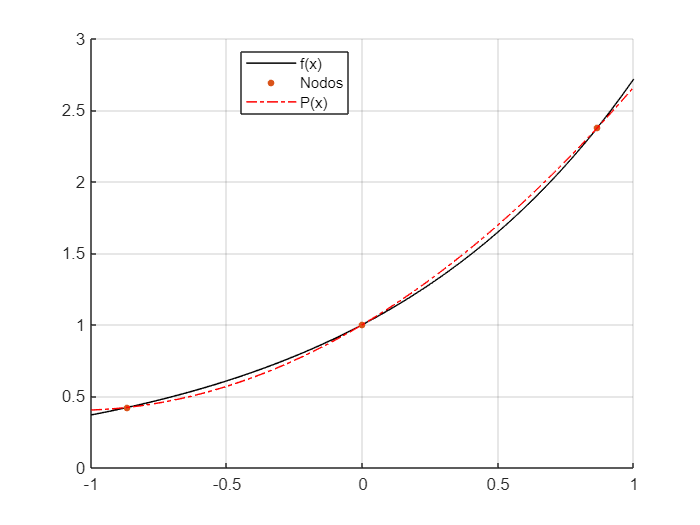

P = @(x) polyval(N, x);
I = [-1, 1];

clf('reset')
hold on
fplot(f, I, 'k', 'DisplayName', 'f(x)')
plot(X, Y, '.', 'MarkerSize', 12, 'DisplayName', 'Nodos')
fplot(P, I,'-.r', 'DisplayName', 'P(x)')
legend('Location', 'best')
grid on
hold off

T = @(x) [chebyshevT(0, x) chebyshevT(1, x) chebyshevT(2, x)];
cheby = @(x) sum(C .* T(x));

clf('reset')
hold on
fplot(f, I, 'k', 'DisplayName', 'f(x)')
plot(X, Y, '.', 'MarkerSize', 12, 'DisplayName', 'Nodos')
fplot(cheby, I,'-.r', 'DisplayName', 'T_n(x)')

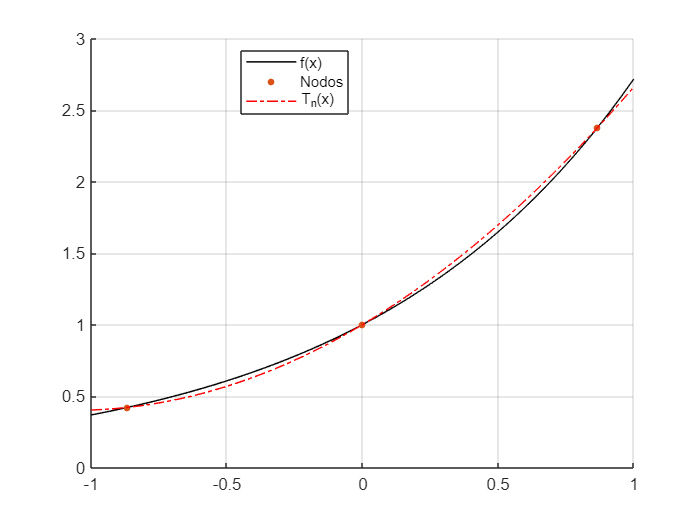

legend('Location', 'best')
grid on
hold off

**2. **Encuentre cotas para el máximo error en los polinomios interpolantes del ejercicio anterior en el intervalo $\left\lbrack -1,1\right\rbrack$


$$|f\left(x\right)\;-p_n \left(x\right)|\;\le \;\frac{1}{\left(n+1\right)!}|f^{\left(n+1\right)} \left(\beta \left(x\right)\right)|\;\prod_{i=1}^n \left(x_i -x\right)\;\;\;\;\;\;\to \;\;\;\frac{1}{2^{n\;} \left(n+1\right)!}|f^{\left(n+1\right)} \left(\beta \left(x\right)\right)|\;\;$$


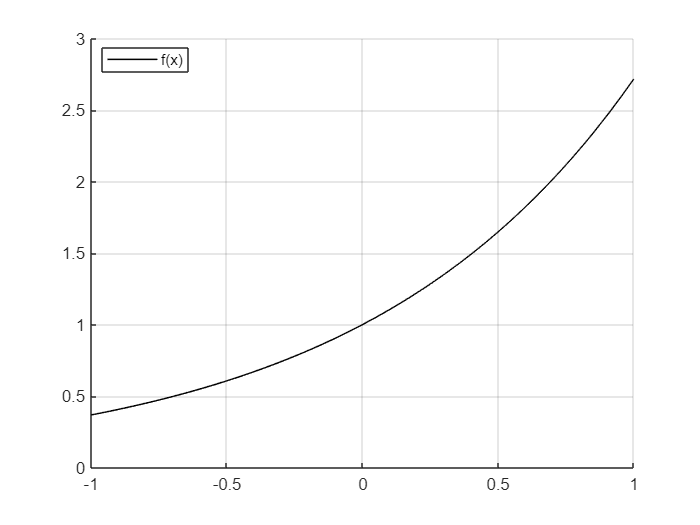

clf('reset')
hold on
fplot(f, I, 'k', 'DisplayName', 'f(x)')
legend('Location', 'best')
grid on
hold off

Error = @(x) abs(d3f(1) / factorial(3) * prod(X - x));
Cota = d3f(1) / factorial(3) * 1 / 2^2;

clf('reset')
hold on
fplot(Error, I, 'k', 'DisplayName', 'Error')

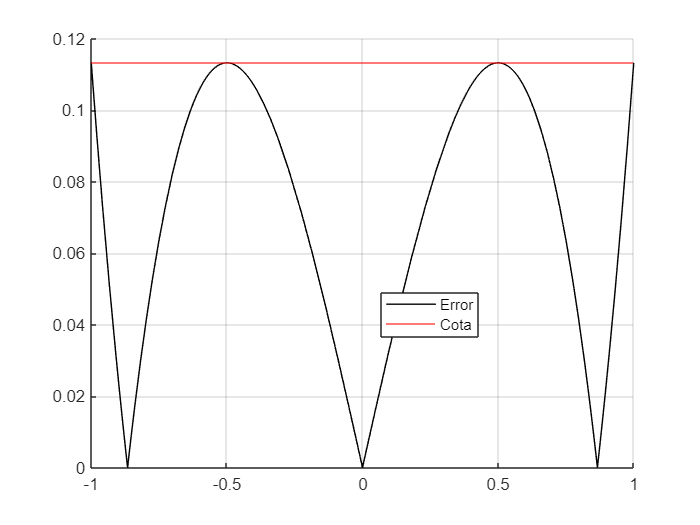

yline(Cota, 'r', 'DisplayName', 'Cota')
legend('Location', 'best')
grid on
hold off

**4. **Utilice los ceros del polinomio de **Chebyshev** de grado 3 trasladados al intervalo $\left\lbrack a,b\right\rbrack$ indicado por medio de un cambio de variable para obtener polinomios interpolantes de grado 2 para las siguientes funciones:

**a) **$f\left(x\right)=1/x$**, **$\left\lbrack 1,3\right\rbrack$**.**

**b) **$f\left(x\right)=e^{-x}$**, **$\left\lbrack 0,2\right\rbrack$**.**

**c) **$f\left(x\right)=x\;\log \left(x\right)$**, **$\left\lbrack 1,3\right\rbrack$**.**

**d) **$f\left(x\right)=1/2\;\cos \left(x\right)+1/3\;\sin \left(3x\right)$**, **$\left\lbrack 0,1\right\rbrack$**.**

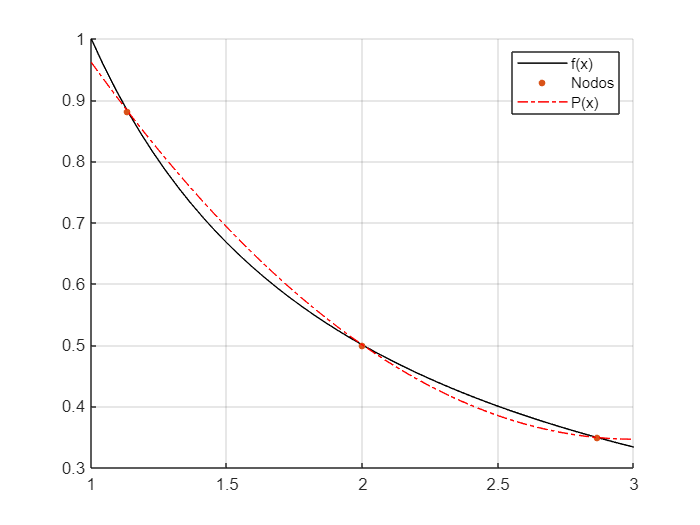

clear
syms f(x)

I = [1, 3];

f(x) = 1 / x;
d3f(x) = diff(f, x, 3);

f = matlabFunction(f);
d3f = matlabFunction(d3f);

[X, Y] = nodoschebyshev(f, 2, 1, 3);

L = lagran(X, Y);

P = @(x) polyval(L, x);

clf('reset')
hold on
fplot(f, I, 'k', 'DisplayName', 'f(x)')
plot(X, Y, '.', 'MarkerSize', 12, 'DisplayName', 'Nodos')
fplot(P, I,'-.r', 'DisplayName', 'P(x)')
legend('Location', 'best')
grid on
hold off

disp(L) % Vector de coeficientes

    0.1538   -0.9231    1.7308



disp(poly2sym(L, x)) % Forma del polinomio simbolico rat

$$\frac{2\,x^{2}}{13}-\frac{12\,x}{13}+\frac{45}{26}$$

digits(32)
disp(vpa(poly2sym(L, x))) % Forma del polinomio simbolico long

$$0.15384615384615384615384615384615\,x^{2}-0.92307692307692307692307692307692\,x+1.7307692307692307692307692307692$$

digits(5)
disp(vpa(poly2sym(L, x))) % Forma del polinomio simbolico short

$$0.15385\,x^{2}-0.92308\,x+1.7308$$

**5. **Encuentre cotas para el máximo error en los polinomios interpolantes del ejercicio anterior en el intervalo $\left\lbrack a,b\right\rbrack$

Recordar, para el caso de escalamiento es necesario realizar el escalado de los valores para la evaluación del error:


$$|f\left(x\right)\;-p_n \left(x\right)|\;\le \;\frac{2\;{\left(b-a\;\right)}^{n+1} }{4^{n+1} \;\left(n+1\right)!}|f^{\left(n+1\right)} \left(\beta \left(x\right)\right)|$$


% Pendiente para realizar: lo revisamos en asesoría

**6. **Encuentre los polinomios de mínimos cuadrados de grados uno, dos y tres para los datos de la siguiente tabla:


$$x_i$$
      
$$1\ldotp 0$$
      
$$1\ldotp 1$$
      
$$1\ldotp 3$$
      
$$1\ldotp 5$$
      
$$1\ldotp 9$$
     
$$2\ldotp 1$$



$$y_i$$
    
$$1\ldotp 84$$
    
$$1\ldotp 96$$
    
$$2\ldotp 21$$
    
$$2\ldotp 45$$
    
$$2\ldotp 94$$
    
$$3\ldotp 18$$


clear

I = [0, 3];

X = [1 1.1 1.3 1.5 1.9 2.1];
Y = [1.84 1.96 2.21 2.45 2.94 3.18];

help lspoly
C1 = lspoly(X, Y, 1); C2 = lspoly(X, Y, 2); C3 = lspoly(X, Y, 3);

P1 = @(x) polyval(C1, x); P2 = @(x) polyval(C2, x); P3 = @(x) polyval(C3, x);

clf('reset')

  Entrada   - X es el vector de abscisas   1 x n
            - Y es el vector de ordenadas  1 x n
            - M es el grado del polinomio por minimos cuadrados
  Salida    - C es la lista de coeficientes para el polinomio



hold on
plot(X, Y, '.r', 'MarkerSize', 12, 'DisplayName', 'Nodos')
fplot(P1, I, 'DisplayName', 'P_1(x)')
fplot(P2, I, 'DisplayName', 'P_2(x)')
fplot(P3, I, 'DisplayName', 'P_3(x)')
legend('Location', 'best')
grid on
hold off
Err1 = Y - P1(X); Error = norm(Err1)^2
Err2 = Y - P2(X); Error = norm(Err2)^2
Err3 = Y - P3(X); Error = norm(Err3)^2

**7. **Proceder como se hizo en el punto anterior, pero con la siguiente tabla:


$$x_i$$
    
$$0\ldotp 0$$
      
$$0\ldotp 15$$
     
$$0\ldotp 31$$
      
$$0\ldotp 5$$
       
$$0\ldotp 6$$
        
$$0\ldotp 75$$



$$y_i$$
    
$$1\ldotp 0$$
    
$$1\ldotp 004$$
    
$$1\ldotp 031$$
    
$$1\ldotp 117$$
    
$$1\ldotp 223$$
    
$$1\ldotp 422$$


% Pendiente para realizar: Lo revisamos en asesoría

**8.** La rata de crecimiento de una colonia de bacterias es desconocida pero se tienen los siguientes datos:

`Tiempo (min)      0     1     2 `

`Número          100   120   160`

Establezca un ajuste exponencial de la forma $y=ce^{\alpha \;x}$ para estos datos. Según este ajuste, ¿cuál será la población a los 4 minutos? 


$$y=ce^{\alpha \;x} \;\;\;\to \;\;\;\log \left(y\right)=\log \left(\;ce^{\alpha \;x} \right)\;\;\;\;\to \;\;\;\log \left(y\right)=\log \left(c\right)+\log \left(e^{\alpha \;x} \right)=\log \left(c\right)+\alpha \;x$$


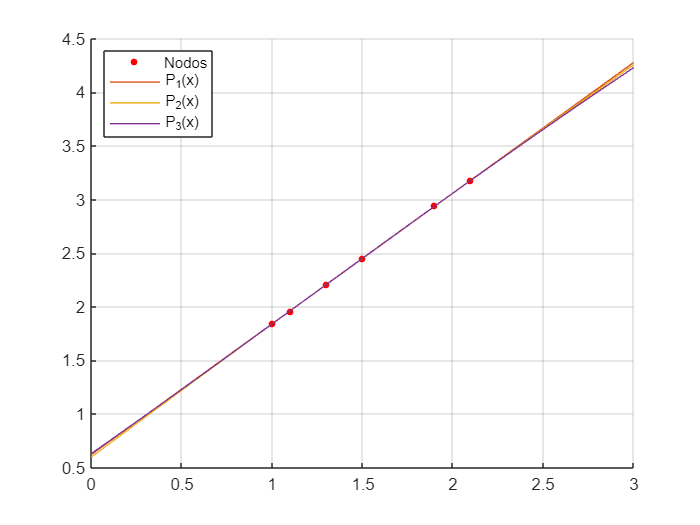

Error = 2.7194e-05

clear

time = 0:2;

Error = 1.8015e-05

bact = [100 120 160];

Error = 1.7407e-05


help lsline
[A, b] = lsline(time, log(bact))
B = exp(b);
predict = @(t) B * exp(A * t);

clf('reset')
hold on
plot(time, bact, '.r', 'MarkerSize', 12, 'DisplayName', 'Data')
fplot(predict, [-1, 3], '-.k', 'DisplayName', 'Prediction')
legend('Location', 'best')
title('Crecimiento de Población')
subtitle('Crecimiento Bacterias vs Tiempo')
ylabel('No. Bacterias')
xlabel('Tiempo')
grid on
hold off

  Entrada  - X es el vector de abscisas   1 x n
           - Y es el vector de ordenadas  1 x n
  Salida   - A es el coeficiente de  x  en  Ax + B
           - B es el coeficiente constante en  Ax + B



El estimado de bacterias para $t=4$ es:

A = 0.2350

b = 4.5876

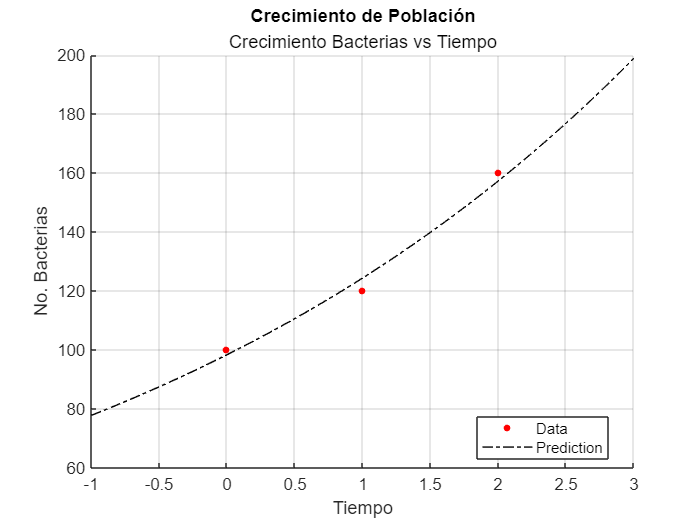

  251.5439



Y =     0.4311    0.6191    2.3198    1.8193


C =    -0.2480    0.2548    1.1923    1.1206


L =    -0.2857    0.8571   -0.2143   -0.3571
    0.4444   -1.1111   -0.4444    1.1111
   -0.2222    0.2222    0.7222    0.2778
    0.0635    0.0317   -0.0635   -0.0317


Y =        21308       38827       48150       66157      114042      149133


disp(predict(4))